%ПИД-регулятор kp = 0.5, ki = 0.2, kd = 0.1
% Constants
ke = 0.4987;
km = ke;
Tm = 0.0886;  
R =  8.8696;
L = 0.0047;
J = 0.0023;
target = 400;
U = 8.05;
M = 0.02; 

kp= 0.5; 
ki= 0.2; 
kd = 0.1;

data=readmatrix('Files_PID\PID_kp0.5_ki0.2_kd0.1.txt');
X=data(:,1);
Y=data(:,2);

Y_fixed=Y(length(Y))

Y_fixed = 440

e_fixed=Y(length(Y))-400 

e_fixed = 40

overshoot=(max(Y)-Y_fixed)/Y_fixed 

overshoot = 0.0068

for i=1:(length(Y))
    if (max(Y(i:length(Y)))<=Y_fixed*1.05) && (min(Y(i:length(Y)))>=Y_fixed*0.95)
        t_transition=X(i) 
       break
    end
end

t_transition = 1.0966

xlim([0 3])
ylim([0 500])
simout=sim('PID_model')

simout =   Simulink.SimulationOutput:

            simulinkPID: [1x1 timeseries] 
                   tout: [11363x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


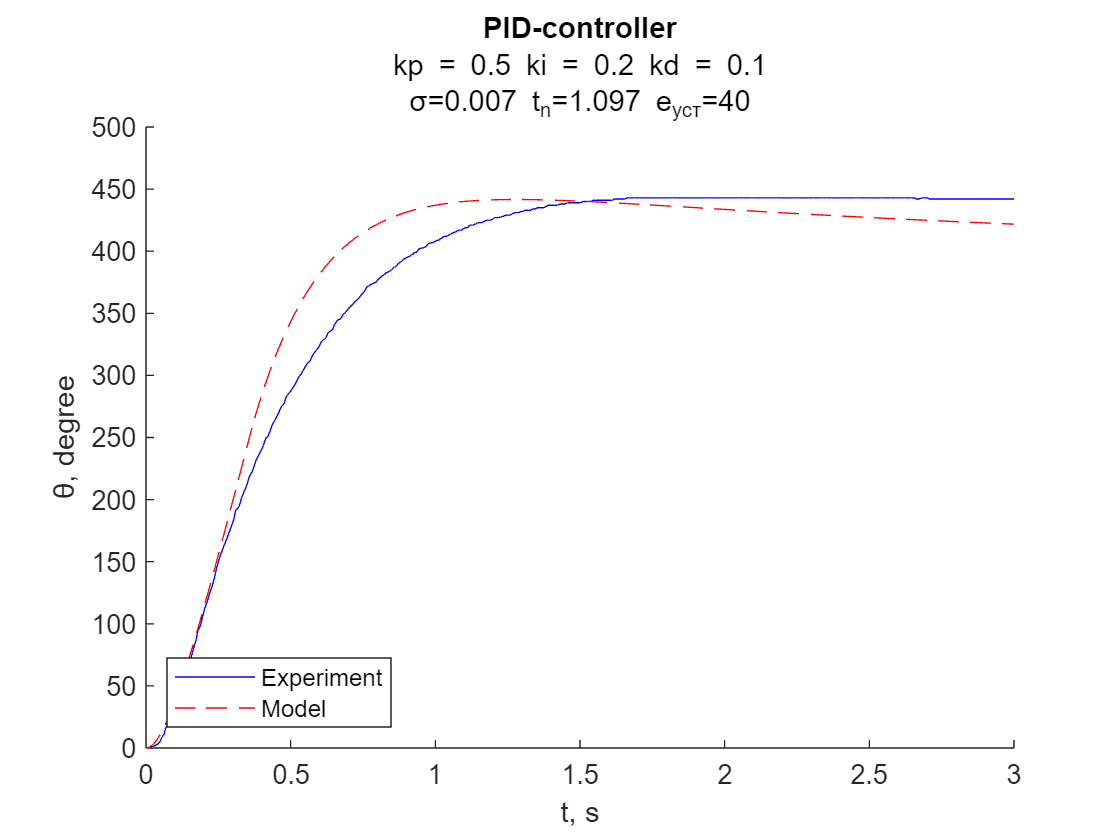



hold on
plot(X,Y,'b')
plot(simout.simulinkPID.Time, simout.simulinkPID.Data,'r--')
h2 = strcat('σ=',string(round(overshoot,3)), ' t_{n}=', string(round(t_transition,3)),' e_{уст}=', string(round(e_fixed,3)));
title('PID-controller',{'kp = 0.5 ki = 0.2 kd = 0.1',h2})
xlabel('t, s')
ylabel('θ, degree')
legend('Experiment', 'Model','Location','southwest')